# Curvature

clc;
clearvars;
close all;
[param, weather, route, driver] = loadData();

long = route.long;
lati = route.lati;

longSmooth = smoothdata(long, 'gaussian', 200, 'SamplePoints', route.dist);
latiSmooth = smoothdata(lati, 'gaussian', 200, 'SamplePoints', route.dist);

#### Curvature

X = [longSmooth, -1*latiSmooth]; %positive input to the function curvature
[cumLength, curvRadius, curvVector] = curvature(X);

invCurvRadius = 1./curvRadius;

invCurvRadiusSmooth = smoothdata(invCurvRadius, 'gaussian', 20, 'SamplePoints', route.dist);

### Plot

#### Geomap

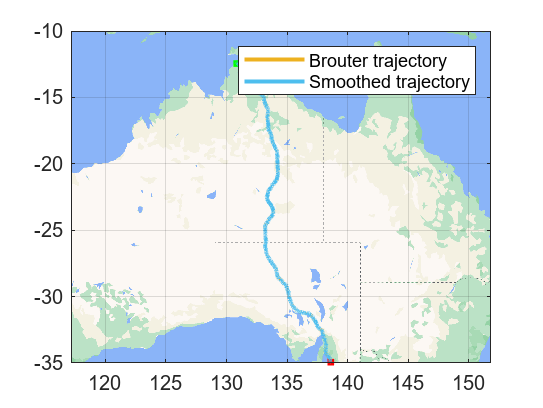

figure
plotTrajectory(long, lati, 'Brouter')
plotTrajectory(longSmooth, latiSmooth, 'Smoothed')
plotGeoMap()
clickableLegend()
hold on
box on
grid on

#### Curvature

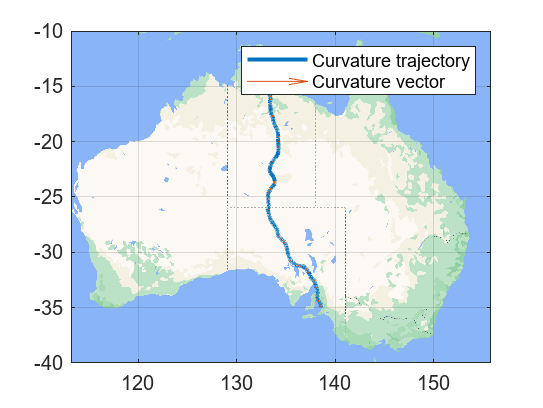

figure
plotTrajectoryCurvature(longSmooth, latiSmooth, 'Curvature', longSmooth, latiSmooth, curvVector)
plotGeoMap()
clickableLegend()
hold on
box on
grid on

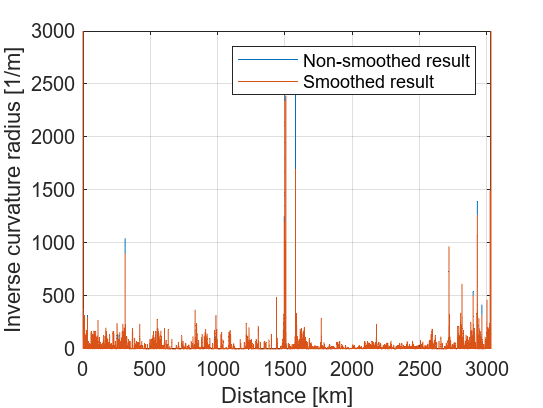


% figure;
% plot(longSmooth, latiSmooth, 'marker','.');grid on; axis equal
% xlabel('Longitude')
% ylabel('Latitude')
% title('2D curve with curvature vectors')
% hold on
% quiver(longSmooth, latiSmooth, curvVector(:,1), curvVector(:,2));
% hold off

figure
plot(route.dist / 1000, invCurvRadius, 'DisplayName', 'Non-smoothed result')
hold on
plot(route.dist / 1000, invCurvRadiusSmooth, 'DisplayName', 'Smoothed result')
ylim([0 3000])
xlabel('Distance [km]')
ylabel('Inverse curvature radius [1/m]')
legend()
clickableLegend
grid on
box on

## Functions

function plotTrajectory(long, lat, name)
h = hggroup('DisplayName', sprintf('%s trajectory', name));
h.Annotation.LegendInformation.IconDisplayStyle = 'on';

plot(h, long(1), lat(1), 'g.', 'DisplayName', sprintf('%s start', name), 'MarkerSize', 10)
plot(h, long(end), lat(end), 'r.', 'DisplayName', sprintf('%s finish', name), 'MarkerSize', 10)
plot(h, long, lat, 'LineWidth', 2, 'DisplayName', sprintf('%s trajectory', name))
end % function


function plotTrajectoryCurvature(long, lat, name, longSmooth, latiSmooth, curvVector)
h = hggroup('DisplayName', sprintf('%s trajectory', name));
h.Annotation.LegendInformation.IconDisplayStyle = 'on';

plot(h, long, lat, 'LineWidth', 2, 'DisplayName', sprintf('%s trajectory', name))
hold on
quiver(longSmooth, latiSmooth, curvVector(:,1), curvVector(:,2), 'DisplayName', sprintf('%s vector', name));

end % function